clc;
clear;
close all;

## Esercizio 1

generi casualmente un numero n intero compreso tra 1 e 40. Dopo aver verificato che il numero inserito sia anche divisibile per 4, si costruisca e si visualizzi la matrice E fatta nel seguente modo

• A ∈ $R^{2p\times 2p}$ contenente elementi uguali a 2p;

• B ∈ R3p×2p e contiene elementi uguali a 3p;

• C contiene elementi nulli;

• D contiene elementi uguali a −2,

dove, p = n/4 . Dedurre le dimensioni di C e D sapendo che E ∈ Rn×n .

Se il numero generato n non dovesse verificare le condizioni richieste, dovrà esserne

generato uno nuovo fino a quando non si ottiene un numero consentito.

n = 4*randi([1 10], 1);
p = n/4;

A = 2*p * ones(2*p);
B = 3*p * ones(3*p, 2*p);
C = zeros(2*p);
D = -2 * ones(p, 2*p);

E1 = [A; C];
E2 = [B; D];

E = [E1 E2]

E =      2     2     3     3
     2     2     3     3
     0     0     3     3
     0     0    -2    -2


clc;
clear;
close all;

## Esercizio 2

crei un test per la risoluzione di un sistema lineare Ax = b con la fattorizzazione P A = LU . In particolare:

• generare le matrici dei coefficienti del sistema di dimensione crescente da 10 a 100 con passo 10, contenenti numeri pseudo-casuali reali compresi tra −20 e 20;

• controllare che la matrice sia invertibile e, in caso negativo, generare una nuova matrice fino a quando non si genera una matrice invertibile;

• trovare le matrici P , L, e U tali che P A = LU ;

• imporre una soluzione nota x di elementi uguali a 1 e calcolare il corrispondente termine noto b;

• calcolare la soluzione x1 del sistema utilizzando la fattorizzazione ottenuta;

• infine, calcolare e visualizzare una tabella in cui compaiono la dimensione della matrice e l’errore relativo tra la soluzione vera x e quella ottenuta x1 .

La funzione [L,U,P] = palu(A) dovrà essere allegata alla fine dello script.

k = 1;
iMin = -20;
iMax = 20;

for i = 10 : 10 : 100
    flag = true;
    while flag
        A = (iMax-iMin) * rand(i) + iMin;
        if(abs(det(A)) > 1e-10)
            flag = false;
        end
    end

    [L, U, P] = palu(A);

    x = ones(i, 1);

    b = A*x;

    y = L\(P*b);
    x1 = U\y;

    errRel(k) = norm(x - x1) / norm(x);
    k = k + 1;
end

dim = 10 : 10 : 100;

t = table(dim', errRel', 'VariableNames', {'Dimensione', 'ErrRel'});
disp(t);

    Dimensione      ErrRel  
    __________    __________

        10        9.7295e-16
        20        2.2359e-15
        30        9.6316e-15
        40        3.1253e-15
        50        2.8214e-15
        60        7.7399e-15
        70         6.816e-15
        80        3.0494e-14
        90        2.2992e-14
       100        9.8526e-15



clc;
clear;
close all;

## Esercizio 3

implementi un test per l’approssimazione della radice positiva dell’equazione nonlineare

utilizzando il metodo di bisezione, partendo dall’intervallo a = 1 e b = 2. Impostare una tolleranza tol = 10−6 e un numero massimo di iterazioni kmax = 200. Infine si stampi, sullo stesso sistema di assi cartesiani, il grafico della funzione f (x) e l’approssimazione ottenuta. Il grafico dovrà essere corredato da un titolo e una legenda.

La funzione [xb, kb] = bisec(f,a,b,tol,kmax) dovrà essere allegata alla fine dello script.

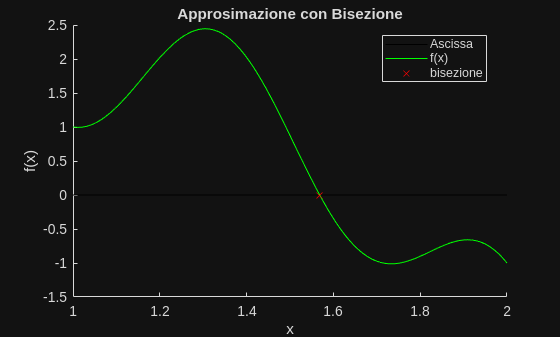

a = 1;
b = 2;
tol = 10e-6;
kmax = 200;

f = @(x) cos(3*pi*x) - x.^3 + x.^2 + 2;

[xb, kb] = bisec(f, a, b, tol, kmax);

figure;
hold on;

x = linspace(a, b);

xlabel("x");
ylabel("f(x)");

title("Approsimazione con Bisezione");

plot(x, zeros(size(x)), "-k", "DisplayName", "Ascissa");
plot(x, f(x), "-g", "DisplayName", "f(x)");
plot(xb, f(xb), "xr", "DisplayName","bisezione");

legend("Location","best");

hold off;

function [L, U, P] = palu(A)

    % palu: metodo per fattorizzare la matrice A con pivoting
    % parziale.
    %   [L, U, P] = palu(A) restituisce una matrice di permutazione,
    % una triangolare superiore e una triangolare inferiore

    [m, n] = size(A);

    % Controlli preliminari sulle dimensioni della matrice e sul
    % determinante
    if m ~= n
        error("la matrice deve essere quadrata");
    end
    if abs(det(A)) < 1e-10
        error("La matrice A è singolare");
    end

    % Inizializzazione matrici
    L = zeros(n);
    P = eye(n);

    
    for k = 1 : n-1

        % Seleziono il pivot massimo in valore assoluto nella colonna
        % k-esima
        [~, index] = max(abs(A(k:n, k)));
        % l è l'indice della riga con pivot massimo
        l = index + k - 1;

        % Scambio delle righe
        A([k l], :) = A([l k], :);
        L([k l], :) = L([l k], :);
        P([k l], :) = P([l k], :);
        
        % Calcolo la nuova riga
        for i = k+1 : n
            m = A(i, k) / A(k, k);

            A(i, :) = A(i, :) - m * A(k, :);

            L(i, k) = m;
        end
    end

    % Assegno il valore corretto alle matrici da restituire
    U = A;
    L = L + eye(n);
end

function [xb, kb] = bisec(f, a, b, tau, kmax)
    
    % bisezione: metodo per trovare un'approssimazione della radice di 
    % f(x) = 0 
    %   [xb, kb] = bisezione(f, a, b, tau, kmax) restituisce l'approssimazione
    %   della radice e il numero di iterazioni effettuate.


    % Inizializzo la variabile fa con f(a) per non doverla calcolare più
    % volte
    fa = f(a);

    % Controllo che nell'intervallo sia contenuta la radice che cerco
    if(fa * f(b) > 0)
        error("Nessuna radice nell'intervallo [%g, %g]", a, b);
    end


    % Inizio algoritmo iterativo da k a kmax
    for kb = 1 : kmax
       
        % Formula bisezione
        xb = (a + b) / 2;
        
        % Aggiorno l'immagine della x trovata per non doverla calcolare più
        % volte
        fxb = f(xb);

        % Controllo la positività dell'immagine trovata e aggiorno
        % l'intervallo
        if(fa * fxb < 0)
            b = xb;
        else
            a = xb;
            fa = fxb;
        end
        
        % Condizioni di arresto
        if abs(fxb) < tau
            return;
        end

    end

    % In caso esca dal ciclo significa che è stato raggiunto il numero
    % massimo di iterazioni senza che il punto trovato abbia raggiunto una
    % tolleranza accettabile
    warning("Iterazioni massime raggiunte");

end